# Lesson 4

Written by Brenda So and Cory Nezin, modified by Guy Bar Yosef.

# Objective

After this class, you should be able to:

- Understand basic debugging in MATLAB

- Understand how to plot graphs and display tables

- Know how to use control sequences (for, if, else, while, try and catch blocks)

- Know how to input and output files in MATLAB

# Debugging in MATLAB

Debugging is the process of analyzing and searching your code for bugs(errors). In this course we will give a simple and practical overview of how to debug your scripts, simply showing how we can use *breakpoints*, as well as the *continue*, *step into*, and *step over* functions.

# Plotting

We are going to go through several plotting schemes and explore how you can customize plotting. We will go through 2D plotting, surface plotting, subplot, stem plot, and 3D plotting.

**NOTE: **There are many more plotting features, we urge you to explore the documentation for whatever graph/plot fits your data best. 

# Plotting in 2D

2D plots are very straightforward, it's what you expect from a textbook or when you are graphing.

% Example 1: Plotting y=x^3
x = -10:0.1:10;
y = x.^3;

figure
plot(x,y,'DisplayName','x^3');              % plotting line graph

total = 55

xlabel('x axis');
ylabel('y axis');
title('Example 1');
grid on;
axis([-10 10 -10 10]);

hold on;                % plotting more than 1 plot on 1 figure rather than overwriting

y2 = x.^2;
plot(x, y2, 'DisplayName','x^2');
legend('show');
% Example 2: Plotting sine and cosine

t = 0:.1:10;
d1 = sin(t);
d2 = cos(t);

figure 
plot(t,[d1.', d2.'])

Summa Cum Laude



title('Trig Functions')
xlabel('time \mus') % \mus is a special symbol. Other examples include: \beta, \pi, \leq, \infty 
ylabel('voltage')
legend('sin','cos', 'Location', 'southwest')
% Here we are going to get a bit fancy and change up some stuff. 
figure;

plot(t,d1,'b-.',t,d2,'rp') % We are changing up the line pattern and color

total = 55

title('Trig Functions')
xlabel('time \mus') % \mus is a special symbol. Other examples include: \beta, \pi, \leq, \infty 
ylabel('voltage')
legend('sin','cos')
xticks(0:pi/2:10)
xticklabels({'0','\pi/2','\pi','3\pi/2','2\pi', '5\pi/2','3\pi'})

# SubPlots

Subplots exist for stylistic purposes. Let's say you have a signal and you want to plot the magnitude and phase of the signal. It would make more sense if the magnitude and phase plots exist in the same figure. There are several examples fo subplot below to explain how it works. Note that linear indexing of plots is different from normal linear indexing. 

You are trying to do something which is not allowed

ans =     97    99
    98   100


ans =     97
    98


a =      1     2     3


b =      1     2     3     4     5


A =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


B =      1     1     1
     2     2     2
     3     3     3
     4     4     4
     5     5     5


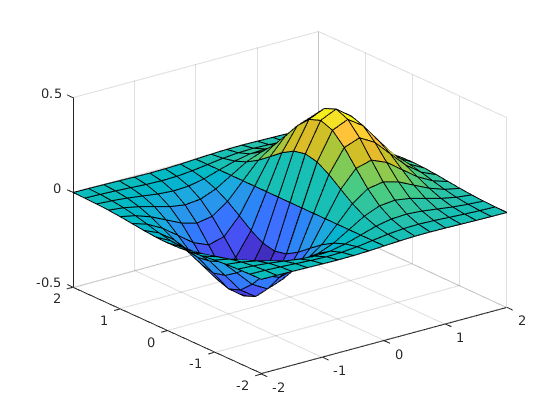

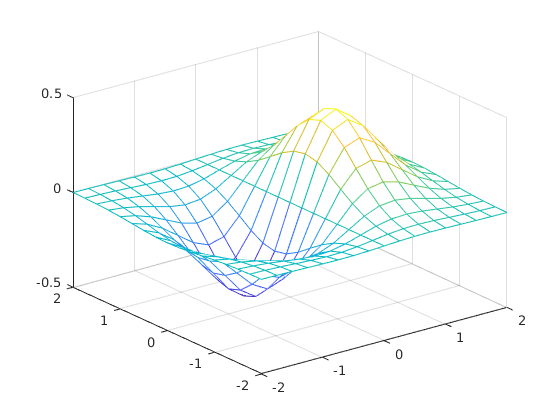

figure

subplot(2,2,1)
plot(t,d1)

hold on;
plot(t,d2)
title('Normal plot'), xlabel('time(s)'), ylabel('Amplitude');

subplot(2,2,2)
plot(t,d1,'b-.',t,d2,'rp')
title('Customized plot'), xlabel('time(s)'), ylabel('Amplitude');

%% Stem plots

C_text = 1×1 cell array
    {4×1 cell}


% stem plots are particularly useful when you are representing digital

C_data0 = 1×4 cell array
    {4×1 int32}    {4×1 double}    {4×1 double}    {4×1 double}


% signals, hence it is good to learn them too!

ans = 4×1 int32 column vector
   1
   2
   3
   4


subplot(2,2,[3 4])
stem(t,d1)
hold on;
stem(t,d2)
title('Stem plots'), xlabel('time(s)'), ylabel('Amplitude');

# 3D and surface plots

% 3D plotting: The helix
t = linspace(0,10*pi);
figure;
plot3(sin(t),cos(t),t)
grid on;
title('Helix'), xlabel('sin(t)'), ylabel('cos(t)'), zlabel('t')
text(0,0,0,'origin')

# Tables

Tables are a great way to clearly display ones results. Conveniently, they are also very simple to use in MATLAB:

Schools = {'Architecture'; 'Engineering'; 'Art'};
Student_Count = [250; 250; 500];
t = table(Schools, Student_Count)

# Control Sequences

Similar to C, MATALB has control sequence commands. Last class we explored for loops and the difference between for loops and vectorization. Even though vectorization is more computationally efficient than loops, sometimes for loops and other control sequences are necessary, such as to perform simulations. 

Assuming that everyone has an understanding of control sequences, we will not delve too deep into the discussion of their mechanics but rather show you the semantics of the statements.

# For Loops

total = 0;
for i = 1:10
    total = total + i;
end
total

# If...Else Statements

vgpa = 1.76;
wgpa = 2.52;
xgpa = 3.55;
ygpa = 3.76;
zgpa = 3.83;
gpa = zgpa;
if gpa < 2
    fprintf('You are in DANGER!!!\n')
elseif gpa >= 2 && gpa < 3.5
    fprintf('You are safe.\n')
elseif gpa >= 3.5 && gpa < 3.7
    fprintf('Cum Laude\n')
elseif gpa >= 3.7 && gpa < 3.8
    fprintf('Magna Cum Laude\n')
elseif gpa >= 3.8 && gpa < 4
    fprintf('Summa Cum Laude\n')
end

# While Loop

total = 0;
i = 0;
while i <= 10
    total = total +i;
    i = i+1;
end
total

# Try and catch blocks

Try and catch allows you to "catch" errors and display error statements. They can also help if you don't know whether a certain statement would run correctly or not and your program depends on that certain line of code. Catching the error can allow you to gaurantee the rest of the program works correctly. 

try
    a = [1 2; 3 4];
    b = [1 2 3 4];
    c = a*b
catch err
    fprintf('You are trying to do something which is not allowed');
    % You can check the documentation for more things you can do with 
    % try-catch blocks, including information you can get from the error.
end

# File I/O

Very often, you would need to process files that are not already in MATLAB. For instance, if you have a comma separated value file (csv), you would need to find a systematic way to load all your data into MATLAB. Moreover, you might also want to export figures and data from MATLAB, hence the need to learn file I/O. We are only convering a subset of file I/O in this section, more information can be found here: [https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html](https://www.mathworks.com/help/matlab/import_export/supported-file-formats.html) .

## Importing data

mypic = load('brenda_so.mat');                      % Import a .mat file
% can open with image(brenda_so.mypic)

[y, Fs] = audioread('hallelujah.wav');              % Import an audio
% can play with sound(y, Fs)

fileID = fopen('grades.txt');
C_text = textscan(fileID,'%s',4,'Delimiter','|')    % Import a textfile
C_data0 = textscan(fileID,'%d %f %f %f')            % Import the data in the textfile  
C_data0{1}

Note that when importing a textfile, it returns an array of cells. 

## Exporting data

save('allData')                  % saves your whole workspace into a .mat file
audiowrite('mySong.wav',y,Fs)    % saves audio
fileID = fopen('myFile.txt','w');
fprintf(fileID,'1 Januar 2014, 20.2, 100.5 \n');
fprintf(fileID,'1 Februar 2014, 21.6, 102.7 \n');
fprintf(fileID,'1 März 2014, 20.7, 99.8 \n');
fclose(fileID);

# Lab

Write a function that takes in an N x 1 vector of standard deviations, $\sigma$, an M x 1 vector of means, $\mu$, and an P x 1 vector of evaluation points.  The function should then plot NxM Gaussian shapes characterized by $F_{i,j} \left(x\right)=\;\frac{1}{\sqrt{2\pi {\sigma^2 }_{ˆi} }}\exp \left(-\frac{{\left(x-u_j \right)}^2 }{2{\sigma_i }^2 }\right)$. (where i ranges from 1 to N and j ranges from 1 to M).  Basically, plot the equation for every combination of $\mu$and $\sigma$.  Add appropriate legend and axis labels.

- First, generate the Gaussian vectors.  This can be done without any loops using *ndgrid*.

- Create a new figure. Enumerate through all of the $\mu 's$and $\sigma 's$ using a double for loop.

- Within the loop, create a legend which identifies each curve by its standard deviation and mean.  For example if you want to add a label for a curve with standard deviation 3 and mean 2, write *legendString = ['\mu = ',num2str(2),' \sigma = ',num2str(3)];* and     *plot(x,yourCurveNameGoesHere,'DisplayName',legendString).* Make sure you *hold on*!

- Finally, give the figure a title, add some labels, and show the legend.

Here is an example of what your final product should look like: